clc; clear; close all

wire1=importdata('wire1sorted.txt');
wire2=importdata('wire2sorted.txt');
wire3=importdata('wire3sorted.txt');
wire4=importdata('wire4sorted.txt');
data = importdata('sharpness.txt');

number_of_wires = 4;
wire_num = data(:,1);
lens = 20; %20 40
if lens == 10
    pixeltoum = 0.65; %um/pixal
elseif lens == 40
    pixeltoum = 0.1625; %um/pixal
elseif lens == 20
    pixeltoum = 0.3250;
end

if number_of_wires == 1
    wire_1 = find(wire_num == 0);
elseif number_of_wires == 2
    wire_1 = find(wire_num == 0);
    wire_2 = find(wire_num == 1);
elseif number_of_wires == 3
    wire_1 = find(wire_num == 0);
    wire_2 = find(wire_num == 1);
    wire_3 = find(wire_num == 2);
elseif number_of_wires == 4
    wire_1 = find(wire_num == 0);
    wire_2 = find(wire_num == 1);
    wire_3 = find(wire_num == 2);
    wire_4 = find(wire_num == 3);
elseif number_of_wires == 5
    wire_1 = find(wire_num == 0);
    wire_2 = find(wire_num == 1);
    wire_3 = find(wire_num == 2);
    wire_4 = find(wire_num == 3);
    wire_5 = find(wire_num == 4);
end

time = linspace(0,round(length(data)/10),length(data))';
sharpness = data(:,2);
wire1_sharp = sharpness(wire_1);
wire1_sharp_time = [time(wire_1), wire1_sharp];

wire2_sharp = sharpness(wire_2);
wire2_sharp_time = [time(wire_2), wire2_sharp];

wire3_sharp = sharpness(wire_3);
wire3_sharp_time = [time(wire_3), wire3_sharp];

wire4_sharp = sharpness(wire_4);
wire4_sharp_time = [time(wire_4), wire4_sharp];


for i = 1:length(data)
    if data(i,1) == 0
        color(i) = "r";
    elseif data(i,1) == 1
        color(i) = "b";
    elseif data(i,1) == 2
        color(i) = "m";
    else
        color(i) = "b";
    end
end

order(1) = 1;
for i = 2:length(data)
    if data(i,1)-data(i-1,1) == 0
        order(i) = order(i-1);
    elseif data(i,1)-data(i-1,1) == 1
        order(i) = order(i-1);
    elseif data(i,1)-data(i-1,1) == -3
        order(i) = order(i-1)+1;
    end
end
order = order';

data(:,3) = order;

itr = data(:,3);
data(:,4) = time;
which_itr = 40;
itr_num = find(itr == which_itr);
itr_data = data(itr_num,:);
wire_1_itr = itr_data(itr_data(:,1) == 0,:);
wire_1_itr(end,:) = [0 0 0 wire_1_itr(end,4)+0.1];

wire_2_itr = itr_data(itr_data(:,1) == 1,:);
wire_2_itr(end,:) = [0 0 0 wire_2_itr(end,4)+0.1];

wire_3_itr = itr_data(itr_data(:,1) == 2,:);
wire_3_itr(end,:) = [0 0 0 wire_3_itr(end,4)+0.1];

wire_4_itr = itr_data(itr_data(:,1) == 3,:);
wire_4_itr(end,:) = [0 0 0 wire_4_itr(end,4)+0.1];

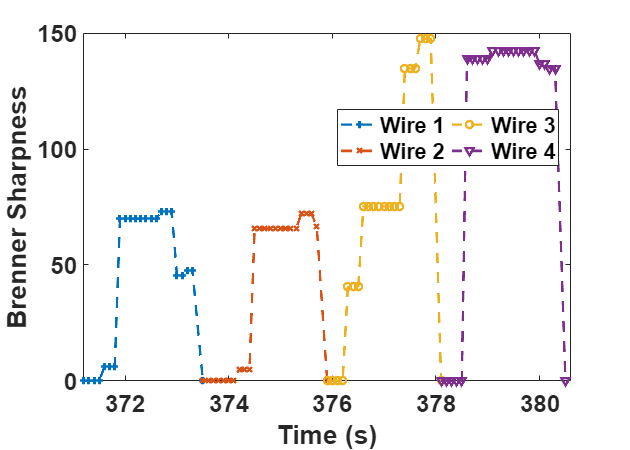

figure(1)
plot(wire_1_itr(:,4),wire_1_itr(:,2),'--+','LineWidth',2); hold on
plot(wire_2_itr(:,4),wire_2_itr(:,2),'--x','LineWidth',2); hold on
plot(wire_3_itr(:,4),wire_3_itr(:,2),'--o','LineWidth',2); hold on
plot(wire_4_itr(:,4),wire_4_itr(:,2),'--v','LineWidth',2); hold off
xlabel('Time (s)','FontSize',20,'FontWeight','bold'); 
ylabel('Brenner Sharpness','FontSize',20,'FontWeight','bold'); 
ax = gca; 
ax.FontSize = 20; 
ax.FontWeight = 'bold';
xlim([wire_1_itr(1,4) wire_4_itr(end,4)+0.1])
legend('Wire 1','Wire 2','Wire 3','Wire 4','Location','best','NumColumns',2)

x0=0; y0=0;
width=700;
height=500;
set(gcf,'position',[x0,y0,width,height])
